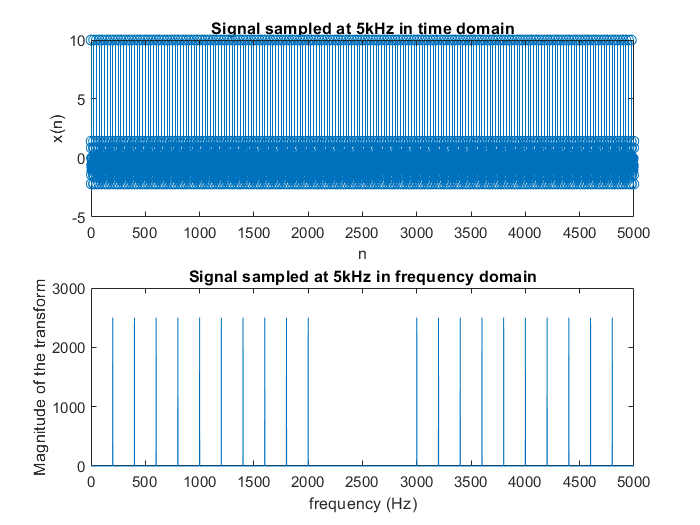

clear all;
close all;
clc;

f = 200; % Signal fundamental frequency of 200Hz.
fs= 5000; % Sampling frequency of 5kHz.
N = 5000; % Since duration of the signal is 1s, and fs=5kHz, we need 5000 samples.
n = 0:N-1;
T= 1/fs; % Sample period.
x = zeros(10,5000); % Matrix for the whole signal
for i = 1:10
    x(i,:) = cos(2*pi*i*f*n*T);
end

signal_supersition = sum(x, 1);
% Plot the orignal signal in time domain.
subplot(2,1,1);
stem(n, signal_supersition);
xlabel('n');
ylabel('x(n)');
title(['Signal sampled at 5kHz in time domain']);
soundsc(signal_supersition);

% Plot the original signal in frequency domain.
fft_for_signal = fft(signal_supersition);
f = 0:4999;
subplot(2,1,2);
plot(f, abs(fft_for_signal));
xlabel('frequency (Hz)');
ylabel('Magnitude of the transform');
title('Signal sampled at 5kHz in frequency domain');
hold off;

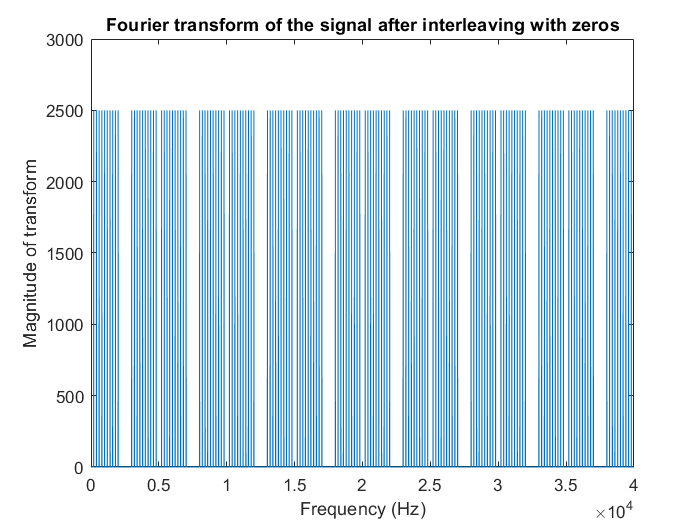

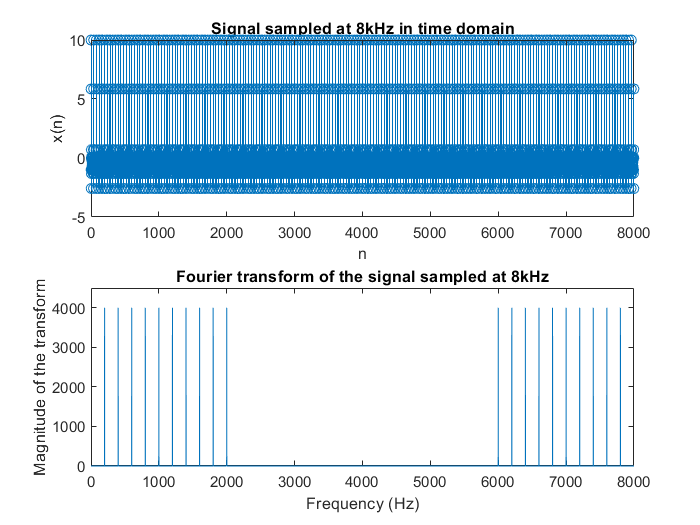

% Call the function to resample the signal to 8kHz.
Resample_5kHz_to_8kHz(signal_supersition);